clear

addpath(genpath('\\one.ferring.com@SSL\DavWWWRoot\team\ps\projects\CLF_PoC\ProjectDocuments\Process development\IRIS dosing development\Final equipment\08-DoE Stirrer'));

addpath(genpath('C:\Users\sagu\Documents\IRIS tests'));

# Import list of IRIS raw data files to analyze

% ListOfFiles = Import_ListOfFiles_v01('IRIS_DoE Stirrer_List Files To Analyze_DoE runs.txt');
ListOfFiles = Import_ListOfFiles_v01('IRIS_DoE Stirrer_List Files To Analyze_Confirmation runs.txt');
% ListOfFiles = Import_ListOfFiles_v01('IRIS_DoE Stirrer_List Files To Analyze_DoE run 1.txt');

# Analyze IRIS raw data files and store results in Structure variable

File: Iris Design_X-2-Short-7mm_Confirmation Run_01.csv


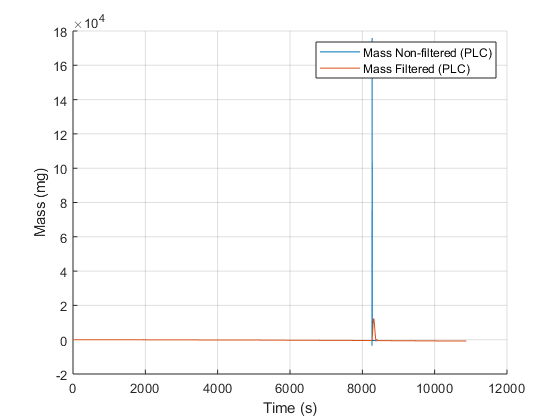

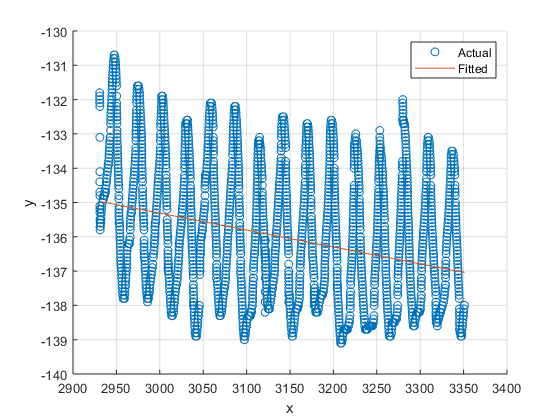

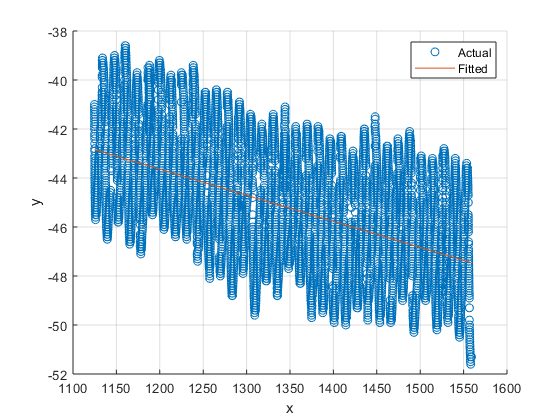

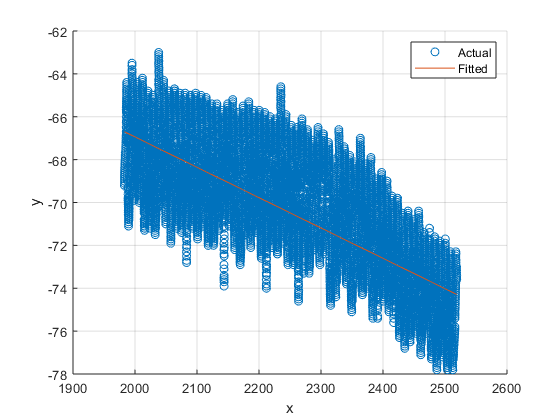

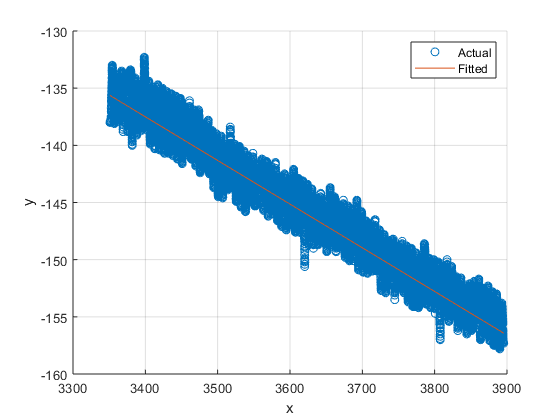

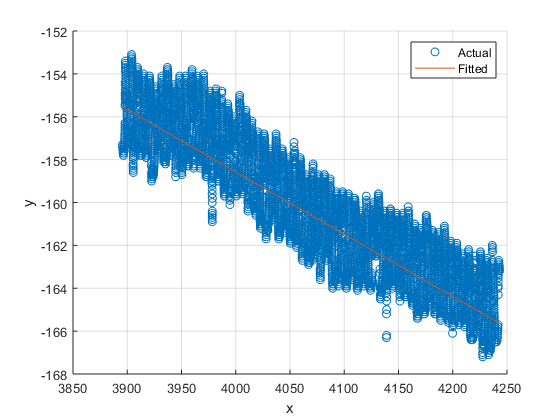

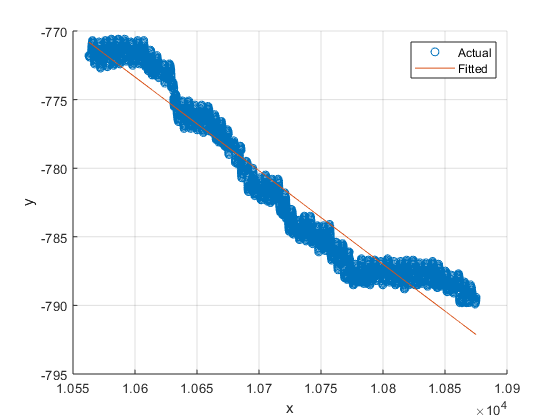

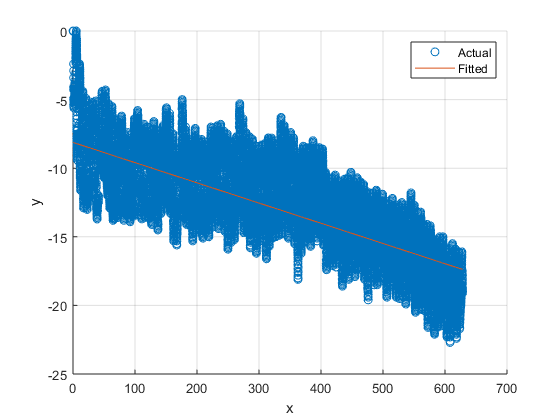

    MotorSpeedLevel    MeanMassFlow       Rsq        TestDuration
    _______________    ____________    __________    ____________

           0                    0             NaN          NaN   
          10             -0.29595        0.079714       420.45   
          20             -0.63773         0.24254       434.35   
          30             -0.84934         0.51599       535.93   
          41              -2.2918         0.93581       544.37   
          46              -1.7417         0.78907       347.61   
          49              -4.0949         0.93876       312.18   
          50             -0.88402         0.52544       628.21   
          51              -3.1128         0.94601       487.91   
          54               -4.557         0.97388       365.11   
          56              -3.3741         0.91117       367.01   
     

Mass Flowrate gain: 0.12015


Calibration linear regression intercept: -1.796


Calibration linear regression R squared: 0.2059


File: Iris Design_X-2-Short-7mm_Confirmation Run_02_resaved.csv


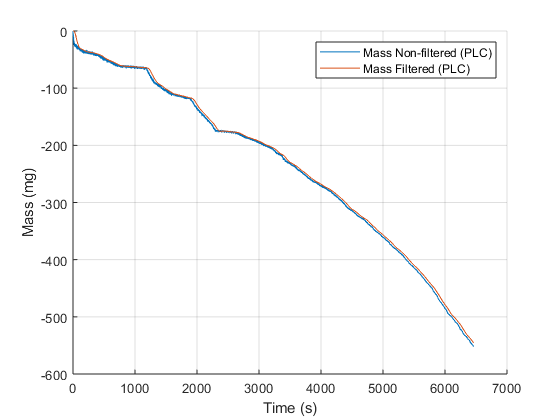

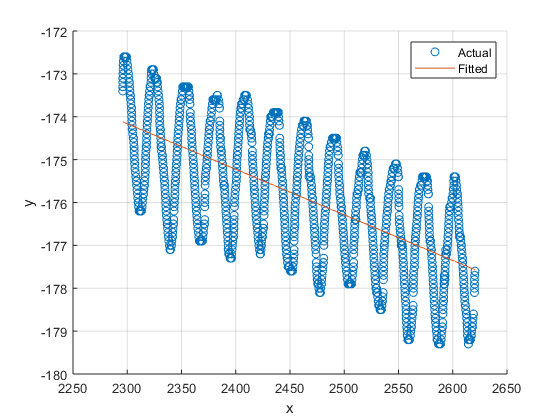

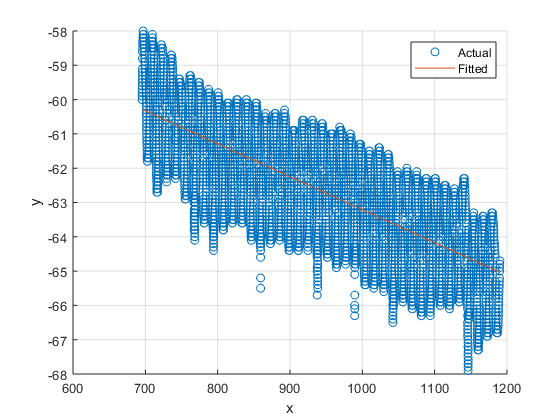

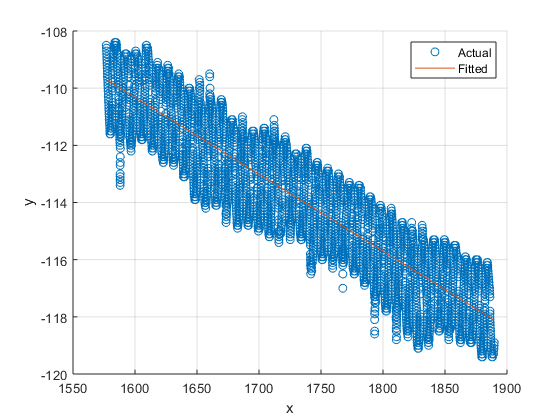

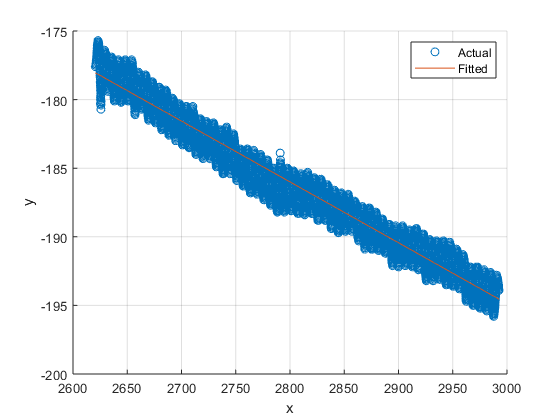

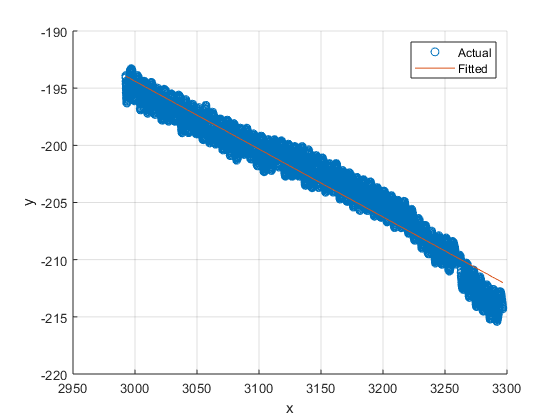

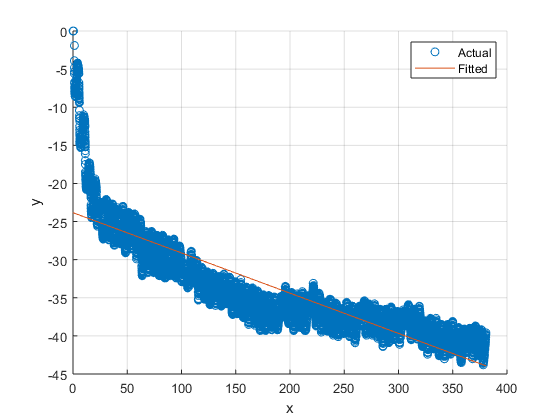

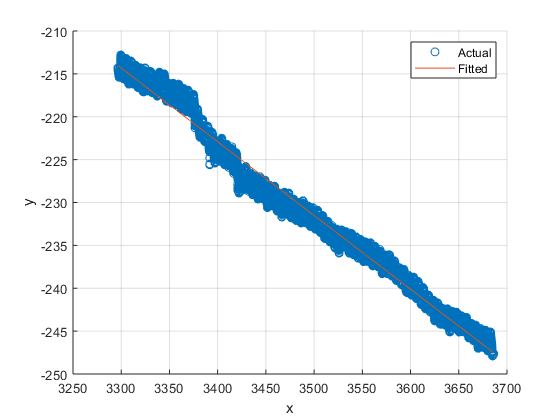

    MotorSpeedLevel    MeanMassFlow      Rsq      TestDuration
    _______________    ____________    _______    ____________

           0                    0          NaN          NaN   
          10             -0.63753      0.36566       324.75   
          20             -0.57623      0.48167       494.67   
          30              -1.6142      0.78888       312.93   
          41              -2.6613      0.94613       371.99   
          46              -3.5628      0.94283       303.93   
          50              -3.1669      0.70694       380.85   
          51              -5.1572       0.9822       389.65   
          56              -4.2866      0.98331       407.21   
          60              -6.0154      0.94326       386.67   
          61              -5.8291      0.98729       341.81   
          66              -4.8605      0.988

Mass Flowrate gain: 0.10382


Calibration linear regression intercept: -1.003


Calibration linear regression R squared: 0.8415


DoEStirrer = struct(...
    'File',{},...
    'RawDataOriginal',{},...
    'RawDataProcessed',{},...
    'MassFlowCalibrationData',{},...
    'MassFlowCalibrationGain',{},...
    'MassFlowCalibrationIntercept',{},...
    'MassFlowCalibrationRsq',{}); % Initialize an empty structure to store analyzed data

for k = 1:length(ListOfFiles)
    
    disp(['File: ',char(ListOfFiles(k))]);
    
    [RawDataOrig,RawDataProc] = IRIS_file_processing_v01(char(ListOfFiles(k)));
    [MassFlowrate_Calibration,MassFlowrate_Calib_Gain,MassFlowrate_Calib_Intercept,MassFlowrate_Calib_rsq] = IRIS_MassFlow_Calib_v01(RawDataProc);
    
    DoEStirrer(k).File = ListOfFiles(k);
    DoEStirrer(k).RawDataOriginal = RawDataOrig;
    DoEStirrer(k).RawDataProcessed = RawDataProc;
    DoEStirrer(k).MassFlowCalibrationData = MassFlowrate_Calibration;
    DoEStirrer(k).MassFlowCalibrationGain = MassFlowrate_Calib_Gain;
    DoEStirrer(k).MassFlowCalibrationIntercept = MassFlowrate_Calib_Intercept;
    DoEStirrer(k).MassFlowCalibrationRsq = MassFlowrate_Calib_rsq;
    
    disp(DoEStirrer(k).MassFlowCalibrationData)
    
    disp(['Mass Flowrate gain: ',num2str(DoEStirrer(k).MassFlowCalibrationGain)]);
    disp(['Calibration linear regression intercept: ',num2str(DoEStirrer(k).MassFlowCalibrationIntercept)]); 
    disp(['Calibration linear regression R squared: ',num2str(DoEStirrer(k).MassFlowCalibrationRsq)]); 

end


clearvars k MassFlowrate_Calib_Gain MassFlowrate_Calib_Intercept MassFlowrate_Calib_rsq MassFlowrate_Calibration RawDataOrig RawDataProc